tic;

### Model frequency as a Normal Distribution

#### Normal Distribution based on raw count

addpath("functions\");
maxLag = 60;
grid = 'continental_europe';
[years,months] = selectTimePeriod(grid)

years = 2019

months = 1

filename = 'processedData/data_continental_europe_2019_01_0'

Elapsed time is 5.440781 seconds.


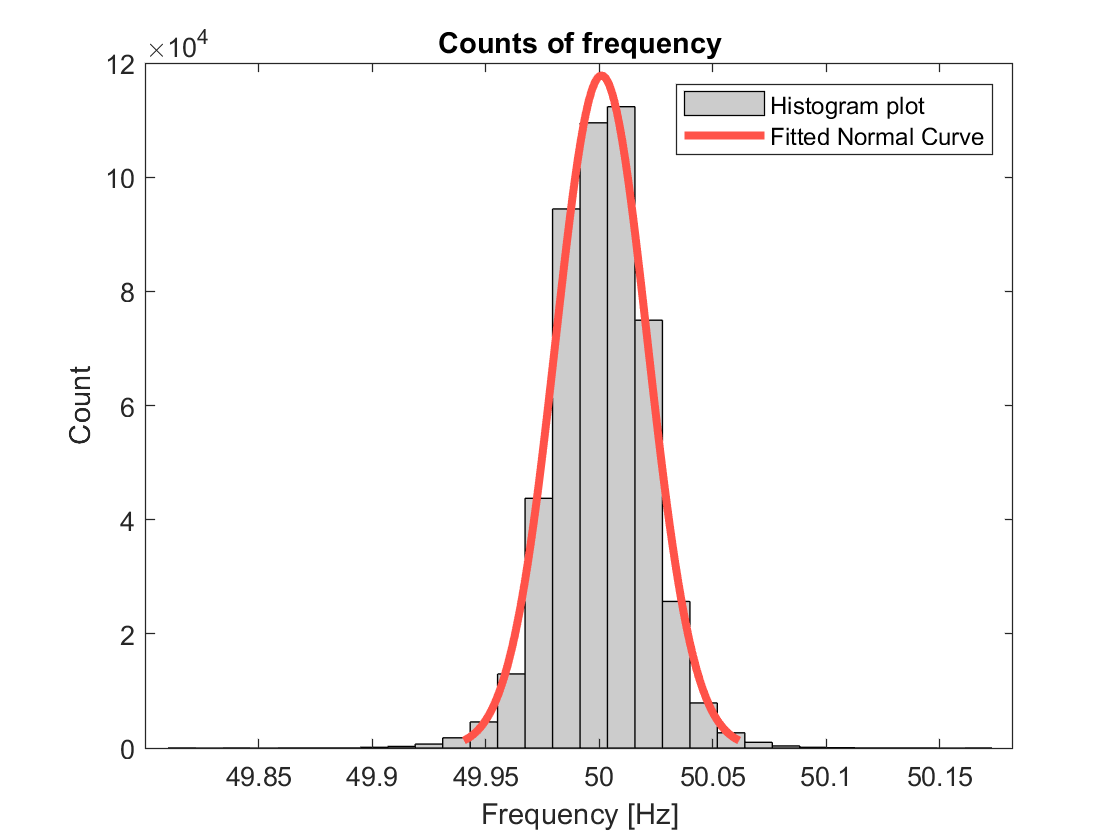

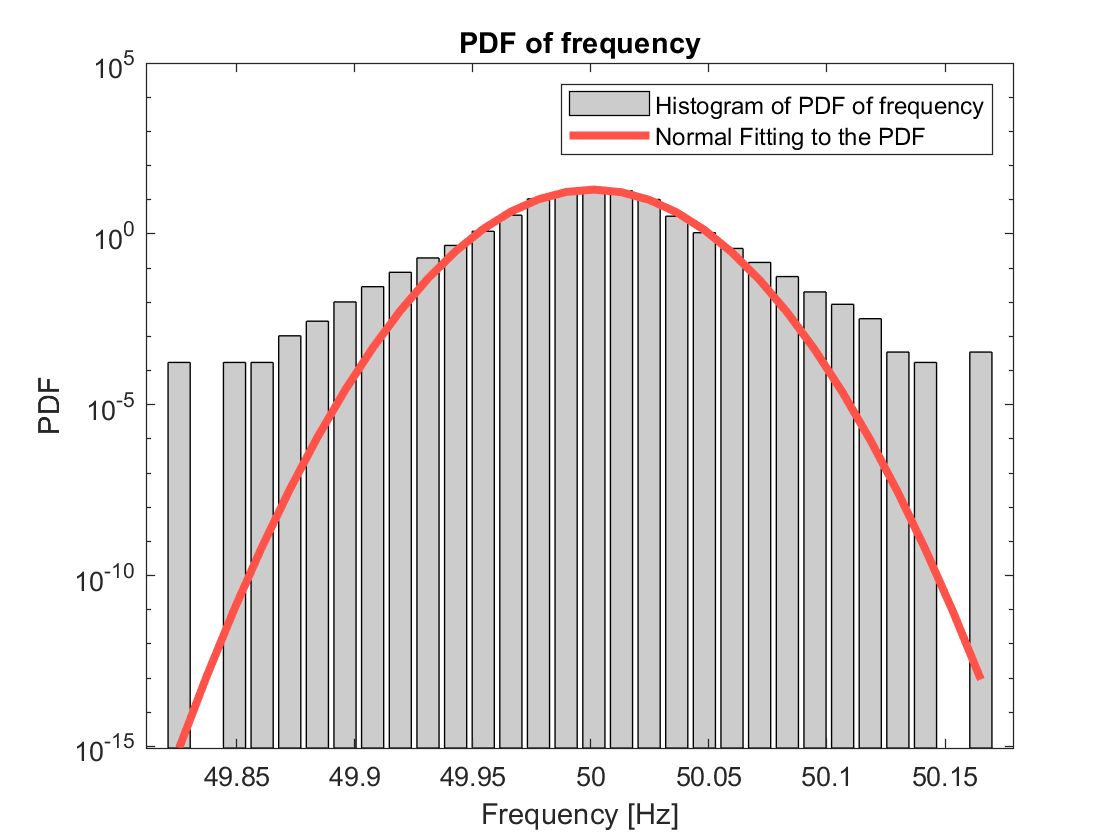

for year = years
    for month = months
        tic;
        if dataExists(grid,year,month)
            filename = selectInput(grid,year,month,0)
            data = readtable(filename);
        else
            continue;
        end
        toc;
        plotNormal(data);
        fautocorr = statsAutocorrelation(grid,data,maxLag);
        writematrix(fautocorr,strcat(filename,'_fautocorr'));
    end
end